## Combined Exp

% Example data
t = (0:0.1:10)'; % Time vector
u = sin(t); % Input data for a system with 2 inputs

% Output data for a system with 2 outputs (example with some noise)
y = [lsim(tf([2], [1 3]), u(:,1), t) + lsim(tf([1], [1 2]), u, t) + 0.1*randn(size(t)), ...
     lsim(tf([1], [1 2]), u(:,1), t) + lsim(tf([3], [1 4]), u, t) + 0.1*randn(size(t))];

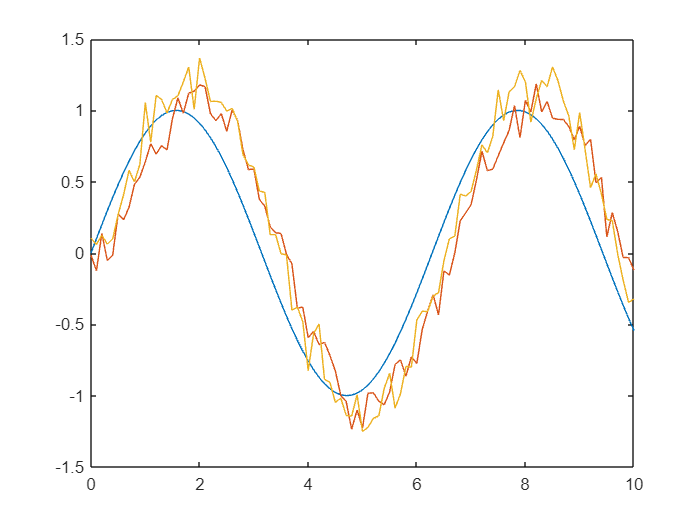

figure, hold on, box on,
plot(t, u, t, y);

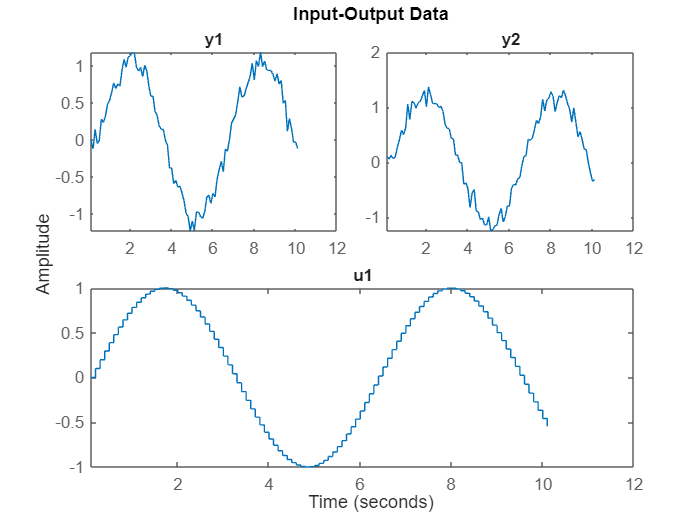

% Create an iddata object with your data
data = iddata(y, u, t(2) - t(1), 'ExperimentName', {'MyMeas1';'MyMeas2'});

figure, box on,
plot(data);

% Initialize cell array for storing models
G_ests = cell(1, num_outputs);

% Define the transfer function structure for the model
K_initial = 1; % Initial guess for K
a_initial = 1; % Initial guess for a
tau_initial = 0.5; % Initial guess for tau

% Loop through each output to estimate the model
for i = 1:num_outputs
    % Create idtf model with initial parameter values
    G0 = idtf(K_initial, [1 a_initial], 'InputDelay', tau_initial);

    % Estimate the model parameters for each output
    G_ests{i} = pem(iddata(y(:, i), u, t(2) - t(1)), G0);
end

% Display the estimated models
for i = 1:num_outputs
    G_ests{i}
end

ans =
  From input "u1" to output "y1":
                  324.7
  exp(-0.5*s) * ---------
                s + 311.4
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                 
Estimated using PEM on time domain data.
Fit to estimation data: 75.08%          
FPE: 0.03248, MSE: 0.03061              
 
Model Properties

ans =
  From input "u1" to output "y1":
                   204
  exp(-0.5*s) * ---------
                s + 179.2
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number

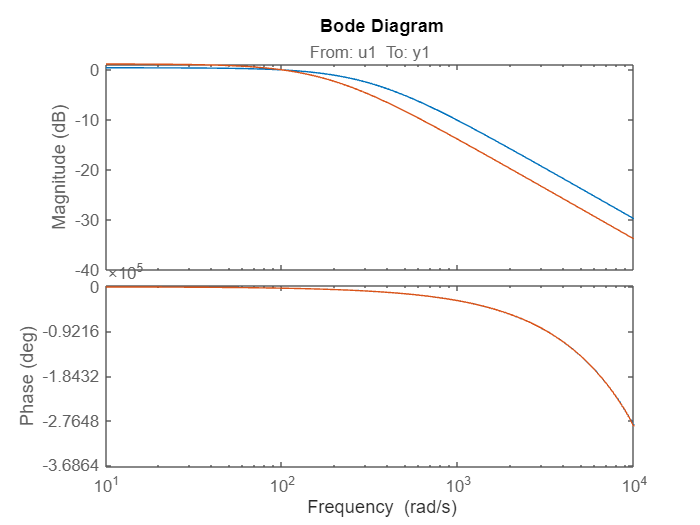

figure, hold on, box on,
for i = 1:num_outputs
    h = bodeplot(G_ests{i});
    % showConfidence(h,3)
end

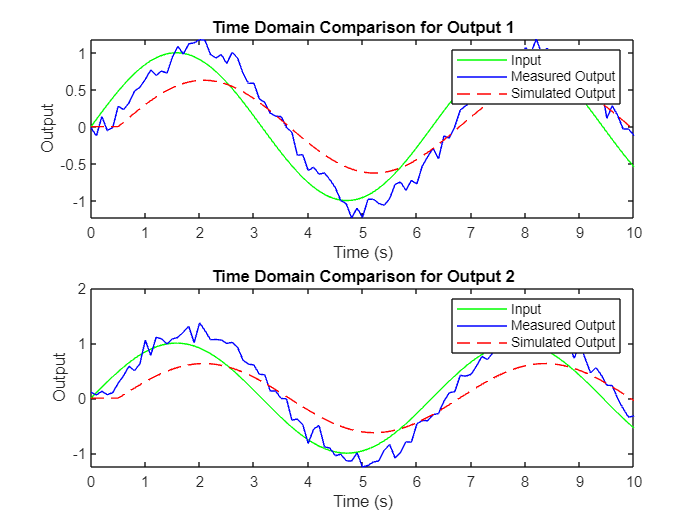

% Initialize cell array for storing sim outputs
y_sims = zeros(size(y));

% Plot the measured output vs. simulated output in the time domain
figure; hold on,
for i = 1:num_outputs
    % Simulate the model output
    y_sims(:, i) = lsim(G_ests{i}, u, t);

    subplot(num_outputs, 1, i);
    plot(t, u, 'g', t, y(:, i), 'b', t, y_est, 'r--');
    legend('Input', 'Measured Output', 'Simulated Output');
    xlabel('Time (s)');
    ylabel('Output');
    title(['Time Domain Comparison for Output ' num2str(i)]);
end

% Compute the frequency response of the measured data using spectral analysis
data_fft = cell(1, num_outputs);
for i = 1:num_outputs
    data_fft{i} = spa(iddata(y(:, i), u, t(2) - t(1)));
end

% Compute the frequency response of the identified models
mag_estimated = cell(1, num_outputs);
phase_estimated = cell(1, num_outputs);
mag_measured = cell(1, num_outputs);
phase_measured = cell(1, num_outputs);
wout = [];

% Loop through each output to compute frequency responses
for i = 1:num_outputs
    % Compute the frequency response of the identified models
    [mag_estimated{i}, phase_estimated{i}, wout] = bode(G_ests{i});

    % Extract magnitude and phase from spa result
    [mag_measured{i}, phase_measured{i}] = bode(data_fft{i}, wout);

    % Convert magnitudes and phases to vectors for plotting
    mag_measured{i} = squeeze(mag_measured{i});
    phase_measured{i} = squeeze(phase_measured{i});
    mag_estimated{i} = squeeze(mag_estimated{i});
    phase_estimated{i} = squeeze(phase_estimated{i});
end

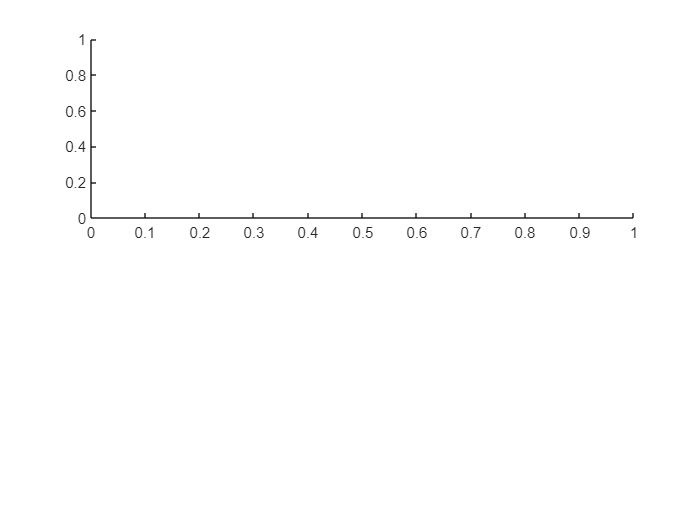

Error using semilogx
Vectors must be the same length.

% Plot the frequency response comparison
figure;
for i = 1:num_outputs
    subplot(num_outputs, 1, i);
    semilogx(wout, 20*log10(mag_measured{i}), 'b', wout, 20*log10(mag_estimated{i}), 'r--');
    legend(['Measured Data Output ' num2str(i)], ['Identified Model Output ' num2str(i)]);
    xlabel('Frequency (rad/s)');
    ylabel(['Magnitude (dB) for Output ' num2str(i)]);
    title(['Frequency Domain Comparison for Output ' num2str(i)]);
end

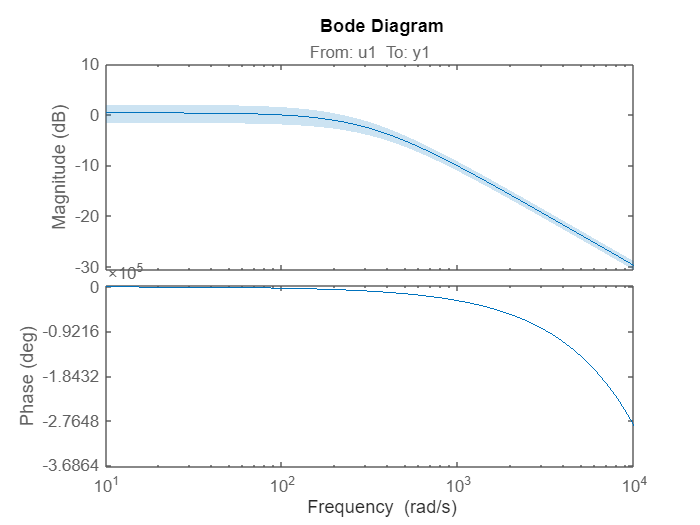

figure,
h = bodeplot(G_ests{1});
showConfidence(h,3)

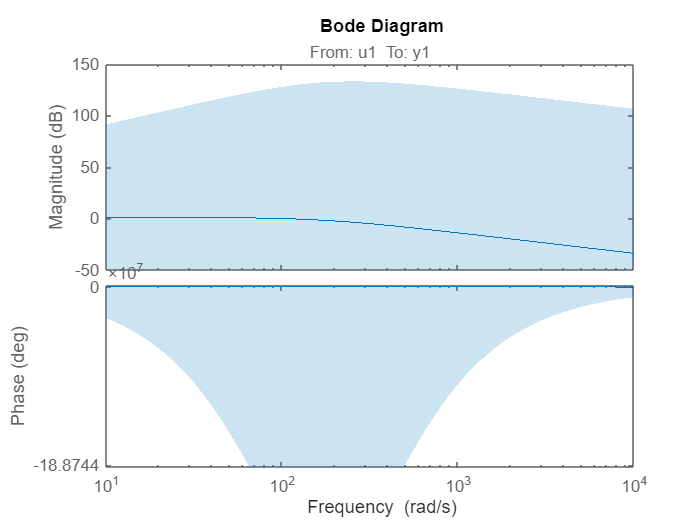


figure,
h = bodeplot(G_ests{2});
showConfidence(h,3)

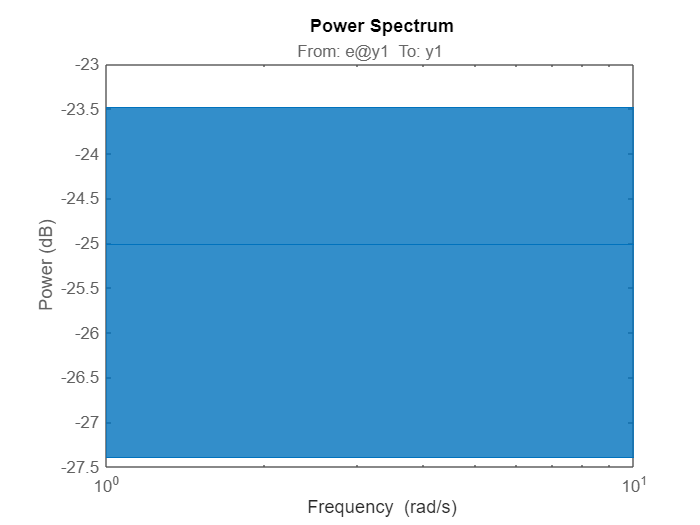

figure,
h = spectrumplot(G_ests{1});
showConfidence(h,3)